clearvars;
close all

%Mediciones del proceso industrial
Tiempo=[0 0.04 0.08 0.12 0.16 0.2 0.24 0.28 0.32 0.36 0.4 0.44 0.48 0.52 0.56 0.6 0.64 0.68 0.72 0.76 0.8 0.84 0.88 0.92 0.96 1]; %segundos
Entrada=[0 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6 6]; %volts
Salida=[0 0 0.33 0.33 0.67 1 1 1 1 1 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165 1.165];%rpm

subplot(2,1,1)
plot(Tiempo,Salida,'g','LineWidth',2)
grid on
hold on
ylabel('Salida (rpm)')

subplot(2,1,2)
plot(Tiempo,Entrada,'r --','LineWidth',2)
grid on
ylabel('Entrada (volts)')
xlabel('Time [seg]')

%Cálculo de la ganancia
DeltaY=Salida(end)-Salida(1);
DeltaU=Entrada(end)-Entrada(1);
K=DeltaY/DeltaU

K = 0.1942


%Cálculo de tiempo muerto
yTheta=0.02*DeltaY + Salida(1);

for i=1:length(Salida)
if Salida(i)<yTheta
    y1(i)=Salida(i); %Valores que son menores a yTheta
end
end
Theta=Tiempo(length(y1)) %Tiempo muerto (cuando y <= yTheta)

Theta = 0.0400


%Cálculo de la constante de tiempo
yTau=0.6321*DeltaY + Salida(1); %Se cumple el 63.21% del cambio

[e index] = min(abs(Salida-yTau)); %índice en vector que corresponde al yTau
Tau=Tiempo(index)-Theta %Constante de tiempo

Tau = 0.1200


%Función de transferencia
Gp_modelo=tf(K,[Tau 1],'inputdelay',Theta)

Gp_modelo =
 
                   0.1942
  exp(-0.04*s) * ----------
                 0.12 s + 1
 
Continuous-time transfer function.
Model Properties



%Ecuación en el tiempo
ymodelo=K*DeltaU*(1-exp(-(Tiempo-Theta)/Tau));
for i=1:length(ymodelo)
if ymodelo(i)<0;
    C_modelo(i)=0; %Concentración inicial (debido @ Theta)
else

    C_modelo(i)=ymodelo(i); %Dinámica de concentración
end
end
Concentracion_modelo=C_modelo+Salida(1) %Modelo considerando condición inicial

Concentracion_modelo =          0         0    0.3302    0.5669    0.7364    0.8579    0.9450    1.0073    1.0520    1.0841    1.1070    1.1234    1.1352    1.1437    1.1497    1.1540    1.1572    1.1594    1.1610    1.1621    1.1629    1.1635    1.1639    1.1642    1.1645    1.1646


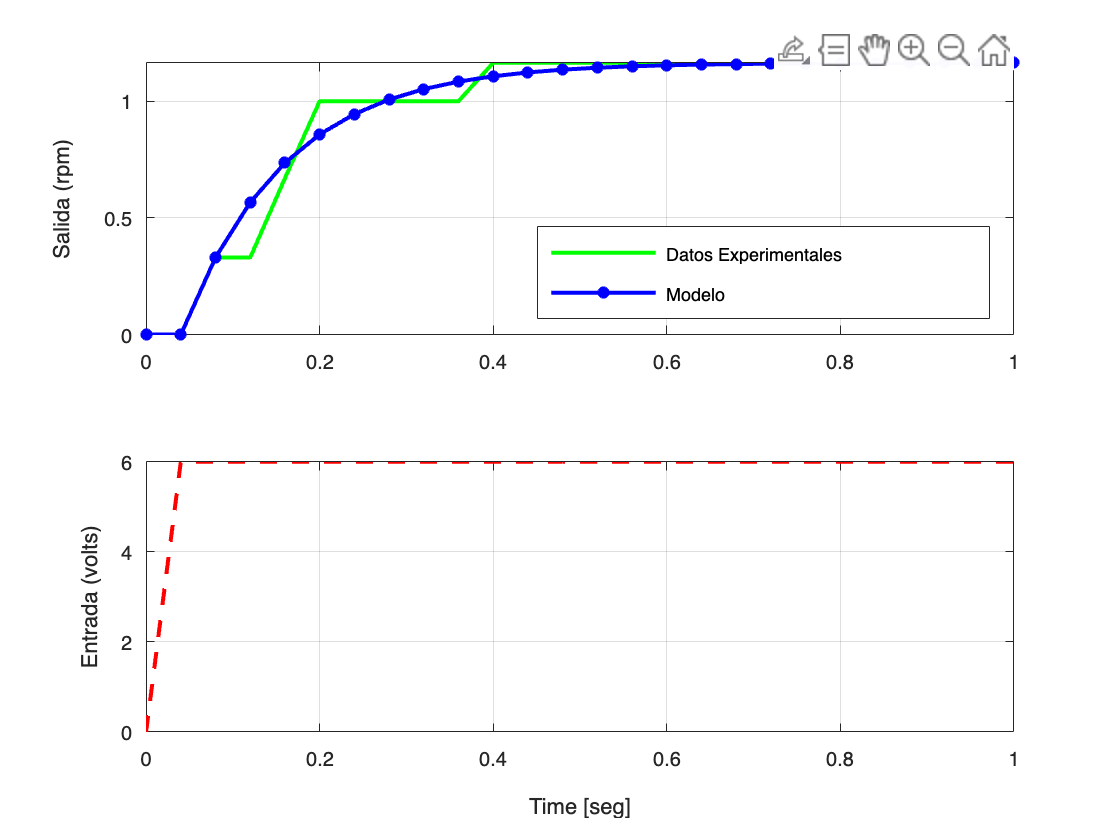


subplot(2,1,1)
plot(Tiempo,Concentracion_modelo,'b *-','LineWidth',2)
legend('Datos Experimentales','Modelo','Location','southeast')


%Cálculo de índice de correlación R^2
Sy=sum((Salida-mean(Salida)).^2)

Sy = 3.4015

Se=sum((Salida-Concentracion_modelo).^2)

Se = 0.1005

R2=(Sy-Se)/Sy

R2 = 0.9705


m=menu('Estrategia del Controlador','Cambios de Setpoint','Rechazo a Perturbaciones');
%Orden de controladores: PID IAE - PID ITAE - PID ISE - PID ITSE
if m==1
    a=[1.086; 0.965; 1.048; 1.042];
    b=[-0.869; -0.85; -0.897; -0.897];
    c=[0.74; 0.796; 1.195; 0.987];
    d=[-0.13; -0.147; -0.368; -0.238];
    e=[0.348; 0.308; 0.987; 0.385];
    f=[0.914; 0.929; 0.238; 0.906];
else
    a=[1.435; 1.357; 1.495; 1.468];
    b=[-0.921; -0.947; -0.945; -0.97];
    c=[0.878; 0.842; 1.101; 0.942];
    d=[-0.749; -0.738; -0.771; -0.725];
    e=[0.482; 0.381; 0.56; 0.443];
    f=[1.137; 0.995; 1.006; 0.939];
end

for i=1:4
    Kp(i)=(1/K)*(a(i)*(Theta/Tau)^b(i));
    if m==1
        Taui(i)=Tau/(c(i)+d(i)*(Theta/Tau));
    else
        Taui(i)=Tau/(c(i)*(Theta/Tau)^d(i));
    end
    Ki(i)=Kp(i)/Taui(i);
    Taud(i)=Tau*(e(i)*(Theta/Tau)^f(i));
    Kd(i)=Kp(i)*Taud(i);
end
Ganancia_Proporcional=Kp(2)

Ganancia_Proporcional = 12.6446

Ganancia_Integral=Ki(2)

Ganancia_Integral = 78.7127

Ganancia_Derivativa=Kd(2)

Ganancia_Derivativa = 0.1684


%discretizacion de PID
T=0.04;
gpz=c2d(Gp_modelo,T)

gpz =
 
            0.05504
  z^(-1) * ----------
           z - 0.7165
 
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


kpz=Kp(2)-Kp(2)*T/(2*Taui(2))

kpz = 11.0704

kiz=Kp(2)*T/Taui(2)

kiz = 3.1485

kdz=Kp(2)*Taud(2)/T

kdz = 4.2105